clc;
clear all;
load("compressed.mat");

yRle = data.y;
dim = size(yRle);
y = zeros(dim(1), 64);
for i = 1:dim(1)
    y(i,:) = irle(yRle{i});
end

cbRle = data.cb;
crRle = data.cr;
dim = size(cbRle);
cb = zeros(dim(1), 64);
cr = zeros(dim(1), 64);
for i = 1:dim(1)
    cb(i,:) = irle(cbRle{i});
    cr(i,:) = irle(crRle{i});
end

clear dim;
clear cbRle;
clear crRle;
clear yRle;
clear i;

dim = size(y);
for i = 2:dim(1)
    y(i,1) = y(i,1) + y(i-1,1);
end
dim = size(cb);
for i = 2:dim(1)
    cb(i,1) = cb(i,1) + cb(i-1,1);
    cr(i,1) = cr(i,1) + cr(i-1,1);
end
clear dim;
clear i;

dim = size(y);
newY = zeros(data.originalLuminanceDim);
columns = data.originalLuminanceDim(2);
row = 1;
column = 1;
for i = 1:dim(1)
    newY(row:row+7, column:column+7) = izigzag(y(i,:));
    if (column+7 == columns)
        row = row+8;
        column = 1;
    else
        column = column + 8;
    end
end
y = newY;
clear newY;
clear row;
clear column;
clear columns;
clear dim;

dim = size(cb);
newCb = zeros(data.originalCrominanceDim);
newCr = zeros(data.originalCrominanceDim);
columns = data.originalCrominanceDim(2);
row = 1;
column = 1;
for i = 1:dim(1)
    newCb(row:row+7, column:column+7) = izigzag(cb(i,:));
    newCr(row:row+7, column:column+7) = izigzag(cr(i,:));
    if (column+7 == columns)
        row = row+8;
        column = 1;
    else
        column = column + 8;
    end
end
cb = newCb;
cr = newCr;
clear newCb;
clear newCr;
clear row;
clear columns;
clear column;
clear i;
clear dim;

quantization_matrix_luminance = [[16,11,10,16,24,40,51,61];
                                [12,12,14,19,26,58,60,55];
                                [14,13,16,24,40,57,69,56];
                                [14,17,22,29,51,87,80,62];
                                [18,22,37,56,68,109,103,77];
                                [24,35,55,64,81,104,113,92];
                                [49,64,78,87,103,121,120,101];
                                [72,92,95,98,112,100,103,99]];

quantization_matrix_crominance = [[17,18,24,47,99,99,99,99];
                                [18,21,26,66,99,99,99,99];
                                [24,26,56,99,99,99,99,99];
                                [47,66,99,99,99,99,99,99];
                                [99,99,99,99,99,99,99,99];
                                [99,99,99,99,99,99,99,99];
                                [99,99,99,99,99,99,99,99];
                                [99,99,99,99,99,99,99,99]];

% dequantizzazione blocchi 8x8
funLuminance = @(block_struct) multiplyByMatrix(block_struct.data, quantization_matrix_luminance);
funCrominance = @(block_struct) multiplyByMatrix(block_struct.data, quantization_matrix_crominance);

y = blockproc(y, [8 8], funLuminance);
cb = blockproc(cb, [8 8], funCrominance);
cr = blockproc(cr, [8 8], funCrominance);

clear funLuminance;
clear funCrominance;
clear quantization_matrix_crominance;
clear quantization_matrix_luminance;

% inversa dct ai blocchi 8x8
fun = @(block_struct) idct2(block_struct.data);

y = blockproc(y, [8 8], fun) + 128;
cb = blockproc(cb, [8 8], fun) + 128;
cr = blockproc(cr, [8 8], fun) + 128;

clear fun;

cb = int32(imresize(cb, 4));
cr = int32(imresize(cr, 4));
y = int32(y);

dim = size(y);

dim =    384   512


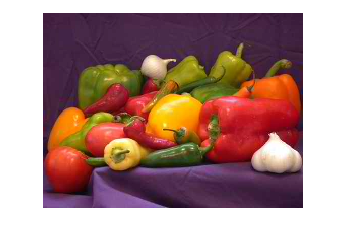

dim(3) = 3;

yCbCr = uint8(zeros(dim));
clear data;
clear dim;
yCbCr(:,:,1) = uint8(y);
yCbCr(:,:,2) = uint8(cb);
yCbCr(:,:,3) = uint8(cr);
clear y;
clear cb;
clear cr;
img = uint8(ycbcr2rgb(yCbCr));
clear yCbCr;
imshow(img);